clear all;
close all
warn = warning ('off','all');

% range, startpoint and target
Xmin=-20;           %range of image
Ymin=-20;
Xmax=20;
Ymax=20;
start_point=[0 ; 0]; % start point of all nodes
var=5;% point generate variance
wt=[60 ; -5]; % target point location

% coefficients
N=150;      % no. of nodes
dt=0.2;     % time increment / time step
times=120; %Number of iterations
R=3.5;   % neighborhood radius
r=3; % node distance limit
r_min=3;% minimum tolerant distance
d=3; % distance of population from the walls
chord_threshold=34; % wall width (chord length) change threshold 
x_chord_begin=40;
x_chord_end=120;
tail_l=0.8;

%velocity parameters
lamda=0.5;  
alpha=2;
alpha_max=3;
beta=2;
gamma=2; 
mu=0.5;

Vblock=0.3;

% define wall models
syms P1(z) P2(z)
P1(z)= 0.008*(z)^2 +100;
P2(z)= -0.008*(z)^2 -100;
Pd1=diff(P1);% derivative of wall equations
Pd2=diff(P2);
steps1=500;
steps2=500;
z1=linspace(Xmin,Xmax,steps1).';
z2=linspace(Xmin,Xmax,steps2).';
yP1=P1(z1);
yP2=P2(z2);
curvexy1=[z1 yP1];
curvexy2=[z2 yP2];
syms y1 x1 y2 x2 cx cy real

% boundaries of wall
syms P1_limit P2_limit
P1_limit(z)= P1(z) -d;
P2_limit(z)= P2(z) +d;
yP1_limit=P1_limit(z1);
yP2_limit=P2_limit(z2);
curvexy_limit1=[z1 yP1_limit];
curvexy_limit2=[z2 yP2_limit];

% directing 
interval=10;
steps_direct=linspace(start_point(1),wt(1),interval).';% x
directx=[steps_direct(2:end-1)];
midpoint=double((P1(directx)+P2(directx))/2); % y
directxy=[directx.'; midpoint.'];
directxy=[directxy,wt];
directxy=wt;%%%% to be changed
directx=directxy(1,:);
directy=directxy(2,:);

% generating the initial population (distributed in acircle with radius 'var')
x=zeros(2,N,times+1); % location of all nodes (uniformly distribute in a circle with radius var)
radius = var*sqrt(rand(1,N)); % Using square root here ensures distribution uniformity by area
t = 2*pi*rand(1,N);
x_cor = radius.*cos(t);
y_cor = radius.*sin(t);
x(:,:,1)=[start_point(1)+x_cor;start_point(2)+y_cor];
x(:,:,2)=[start_point(1)+x_cor;start_point(2)+y_cor];

% define all variables
u=zeros(2,N,times+1); % velocity of all nodes
ua=zeros(2,N,times+1); % heading target velocity of all nodes
ub=zeros(2,N,times+1);% reunion velocity
uc=zeros(2,N,times+1); % coherent motion velocity
delta=zeros(2,N,times+1);
ug=zeros(2,N,times); % gravity center velocity
dist=zeros(N,times); % distance from each node to target
phi=zeros(2,N,times+1);
flag_edge=zeros(N,times);
chord_length=zeros(N,times);
chord_centre=zeros(2,N,times);
r_change=r*ones(N,times);
alpha_change=alpha*ones(N,times+1);
targetxy=zeros(2,N,times);
dist_nodek_alltime=zeros(N,N,times);
vind_all_include=cell(N);
tailxy=zeros(2,N,times+1);
circle_cent=zeros(times,2);

% initialize velocity 
u(:,:,2)=(wt-x(:,:,1))./vecnorm(wt-x(:,:,1));
% block
circle_cent(2,:)=[10 -4];

% at time t, location is updated by u(:,k,t+1)
for t=2:times
    max_all_x=max(x(1,:,t));
    if max_all_x < directx(end)
        tind=find(directx>max_all_x | directx==directx(end),1);% find the next directing point 
        targetxy(:,:,t)=repmat(directxy(:,tind),1,N);
    else
        for k=1:N
            if x(1,k,t) >= directx(end)
                targetxy(:,k,t)=[Xmax;x(2,k,t)];
            else
                targetxy(:,k,t)=directxy(:,end);
            end
        end
    end
    dist(:,t)=vecnorm(targetxy(:,:,t)-x(:,:,t)).'; % dist between each node and target
    dist_nodek=zeros(N,N); % distance between every two nodes (l,k)
    
    
    % distance from node to the closer wall
    pointsxy=x(:,:,t).';
    [xy1,distances1,~] = distance2curve(curvexy1,pointsxy,'linear');
    [xy2,distances2,~] = distance2curve(curvexy2,pointsxy,'linear');
    wallpoints1=xy1.';
    wallpoints2=xy2.';

    % distance from node to block
    distance_cent=vecnorm(pointsxy-circle_cent(t,:),2,2);
    distance_block=distance_cent;

    for k=1:N
        % update heading target velocity / avoid collision velocity
        ua_raw=[];
        if distance_block(k)<=1.5*d
            ua_raw=[ua_raw 2*(1.5*d-distance_block(k))*(x(:,k,t)-circle_cent(t,:).')./distance_block(k)];
            ua_raw=[ua_raw (targetxy(:,k,t)-x(:,k,t))./dist(k,t)];
        else
            ua_raw=[ua_raw (targetxy(:,k,t)-x(:,k,t))./dist(k,t)];
        end
        ua(:,k,t+1)=mean(ua_raw,2);

        % update neighbourhood
        dist_nodek(:,k)=vecnorm(x(:,:,t)-x(:,k,t)).';
        dist_nodek_alltime(:,k,t)=dist_nodek(:,k);
        vind=find(dist_nodek(:,k)<=R & dist_nodek(:,k)>0); % index of neighbourhood (doesn't include itself)
        vind_all_include{k}=find(dist_nodek(:,k)<=R); % index of  neighbourhood (include itself)
        vind_nonneigh=find(dist_nodek(:,k)>R);% index of outside neighbourhood 
        Nk=length(vind_all_include{k}); % number of neighbours of k

        % update gravity center velocity
        ug(:,k,t)=mean(phi(:,vind_all_include{k},t),2);

        % reunion 
        % decide which edge
        W=[u(1,k,t)/norm(u(:,k,t)) -u(2,k,t)/norm(u(:,k,t)); u(2,k,t)/norm(u(:,k,t)) u(1,k,t)/norm(u(1,k,t))]; 
        xlk=zeros(2,N);
        for l=vind  % just care about neighbor fish
            xlk(:,l)=W'*(x(:,l,t)-x(:,k,t)); % (W times every relative location of fish k)
        end
        if xlk(1,:)==-abs(xlk(1,:)) % (all negative, no node l lies in the front of k) k is at front
           flag_edge(k,t)=1;
        elseif xlk(2,:)==abs(xlk(2,:)) % (all positive, all nodes l lie in left of node k) l(s) are all at left, k is at right edge
           flag_edge(k,t)=2;
        elseif xlk(2,:)==-abs(xlk(2,:)) % l(s) are all at right, k is at left edge
           flag_edge(k,t)=3;
        else 
           flag_edge(k,t)=0;
        end
       
        % update coherent motion velocity (avoid collisions)
        if Nk > 1
            delta(:,k,t)=(1/(Nk-1)) * sum((1-r_change(k,t)./dist_nodek(vind,k)).' .*  (x(:,vind,t)-x(:,k,t)),2); % 重合
        end
        uc(:,k,t+1)=(1-lamda)*ug(:,k,t)+gamma*delta(:,k,t);
        
        % update velocity of each node 
        u(:,k,t+1)=lamda*(alpha_change(k,t+1).*ua(:,k,t+1)+beta*ub(:,k,t))+uc(:,k,t+1);

        % update phi (local center of gravity velocity elements)
        phi(:,k,t+1)=(1-mu)*ug(:,k,t)+mu*u(:,k,t+1);

        % update location
        x(:,k,t+1)=x(:,k,t)+dt*u(:,k,t+1);        
    end

    % update block
    if circle_cent(t,2) >= 3
    Vblock=-Vblock; 
    elseif circle_cent(t,2) <= -7
        Vblock=-Vblock;
    end
    circle_cent(t+1,:)=circle_cent(t,:)+Vblock*[0 1];

    % tail generation
    % unit velocity
    u_mag=repmat(vecnorm(u(:,:,t+1)),2,1);
    u_unit=u(:,:,t+1)./u_mag;
    % tail point
    tailxy(:,:,t)=x(:,:,t)-tail_l*u_unit;


    % set reunion velocity
    % find the nearest edge (different from itself)
    for k=1:N
        flag_out_neigh=flag_edge(:,t);
        flag_out_neigh(vind_all_include{k})=0;% flag for nodes outside the neighbour of node k
        if flag_edge(k,t)==1 % front
           tb =find(flag_out_neigh == 1); % the index of same edges
           if length(tb) == 0
               ub(:,k,t+1)=zeros(2,1);
           else
               dist_kl=dist_nodek(tb,k);    
               [~, ind]= min(dist_kl);
               l=tb(ind);
               ub(:,k,t+1)= (x(:,l,t) - x(:,k,t))/norm(x(:,l,t) - x(:,k,t));
           end
       
        elseif flag_edge(k,t)==2 % right
           tb =find(flag_out_neigh == 2); % the index of same edges
           if length(tb) == 0
               ub(:,k,t+1)=zeros(2,1);
           else
               dist_kl=dist_nodek(tb,k);    
               [~, ind]= min(dist_kl);
               l=tb(ind);
               ub(:,k,t+1)= (x(:,l,t) - x(:,k,t))/norm(x(:,l,t) - x(:,k,t));
           end

        elseif flag_edge(k,t)==3 % left
           tb =find(flag_out_neigh == 3); % the index of same edges
           if length(tb) == 0
               ub(:,k,t+1)=zeros(2,1);
           else
               dist_kl=dist_nodek(tb,k);    
               [~, ind]= min(dist_kl);
               l=tb(ind);
               ub(:,k,t+1)= (x(:,l,t) - x(:,k,t))/norm(x(:,l,t) - x(:,k,t));
           end
        else 
            ub(:,k,t+1)=zeros(2,1);
        end
    end 
    t
end

t = 2

t = 3

t = 4

t = 5

t = 6

t = 7

t = 8

t = 9

t = 10

t = 11

t = 12

t = 13

t = 14

t = 15

t = 16

t = 17

t = 18

t = 19

t = 20

t = 21

t = 22

t = 23

t = 24

t = 25

t = 26

t = 27

t = 28

t = 29

t = 30

t = 31

t = 32

t = 33

t = 34

t = 35

t = 36

t = 37

t = 38

t = 39

t = 40

t = 41

t = 42

t = 43

t = 44

t = 45

t = 46

t = 47

t = 48

t = 49

t = 50

t = 51

t = 52

t = 53

t = 54

t = 55

t = 56

t = 57

t = 58

t = 59

t = 60

t = 61

t = 62

t = 63

t = 64

t = 65

t = 66

t = 67

t = 68

t = 69

t = 70

t = 71

t = 72

t = 73

t = 74

t = 75

t = 76

t = 77

t = 78

t = 79

t = 80

t = 81

t = 82

t = 83

t = 84

t = 85

t = 86

t = 87

t = 88

t = 89

t = 90

t = 91

t = 92

t = 93

t = 94

t = 95

t = 96

t = 97

t = 98

t = 99

t = 100

t = 101

t = 102

t = 103

t = 104

t = 105

t = 106

t = 107

t = 108

t = 109

t = 110

t = 111

t = 112

t = 113

t = 114

t = 115

t = 116

t = 117

t = 118

t = 119

t = 120


% gennerate tail matrix
tail_draw=zeros(2,3*N,times);
for t=1:times
    for k=1:N
        tail_draw(:,3*(k-1)+1,t)=x(:,k,t);
        tail_draw(:,3*(k-1)+2,t)=tailxy(:,k,t);
        tail_draw(:,3*(k-1)+3,t)=[NaN;NaN];
    end
end
Xtail=squeeze(tail_draw(1,:,:));
Ytail=squeeze(tail_draw(2,:,:));

t = 20

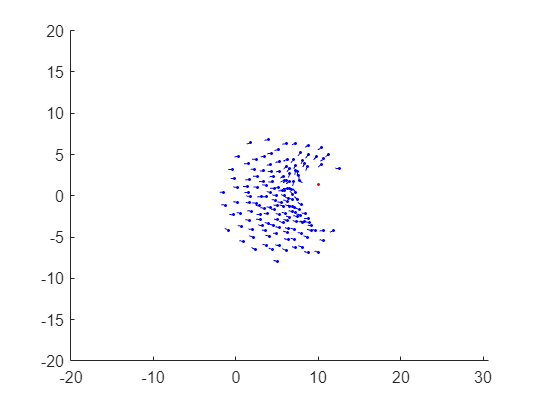

% plot figure
for t=20
    t
    figure;
    hold on;
    % block
    scatter(circle_cent(t,1),circle_cent(t,2),'.','red');
    % nodes
    scatter(x(1,:,t),x(2,:,t),'.','b');
    % tail
    plot(Xtail(:,t), Ytail(:,t), '-b');
    % start and end points
%     scatter(wt(1),wt(2),'*','r');
%     fill([wt(1)-0.5,wt(1)+0.5,wt(1)+0.5,wt(1)-0.5], [wt(2)-0.5,wt(2)-0.5,wt(2)+0.5,wt(2)+0.5], 'r', 'EdgeColor', 'none')
%     scatter(start_point(1),start_point(2),'*','black')
    % axis (xy limit)
    axis([Xmin Xmax Ymin Ymax]);
    axis equal
    hold off
end  

%plot video
for t=2:times
    t
    figure('Visible', 'off');
    hold on;
    % block
    scatter(circle_cent(t,1),circle_cent(t,2),'.','red');
    % nodes
    scatter(x(1,:,t),x(2,:,t),'.','b');
    % tail
    plot(Xtail(:,t), Ytail(:,t), '-b');
    % start and end points
%     fill([wt(1)-0.5,wt(1)+0.5,wt(1)+0.5,wt(1)-0.5], [wt(2)-0.5,wt(2)-0.5,wt(2)+0.5,wt(2)+0.5], 'r', 'EdgeColor', 'none')
%     scatter(start_point(1),start_point(2),'*','black')
    % axis (xy limit)
    axis([Xmin Xmax Ymin Ymax]);
    axis equal
    hold off

    drawnow
    ax = gca;
    ax.Units = 'pixels';
    pos = ax.Position;
    marg = 30;
    rect = [-marg, -marg, pos(3)+2*marg, pos(4)+2*marg];
    M(t-1) = getframe(gca,rect);
    ax.Units = 'normalized';
end  

t = 2

t = 3

t = 4

t = 5

t = 6

t = 7

t = 8

t = 9

t = 10

t = 11

t = 12

t = 13

t = 14

t = 15

t = 16

t = 17

t = 18

t = 19

t = 20

t = 21

t = 22

t = 23

t = 24

t = 25

t = 26

t = 27

t = 28

t = 29

t = 30

t = 31

t = 32

t = 33

t = 34

t = 35

t = 36

t = 37

t = 38

t = 39

t = 40

t = 41

t = 42

t = 43

t = 44

t = 45

t = 46

t = 47

t = 48

t = 49

t = 50

t = 51

t = 52

t = 53

t = 54

t = 55

t = 56

t = 57

t = 58

t = 59

t = 60

t = 61

t = 62

t = 63

t = 64

t = 65

t = 66

t = 67

t = 68

t = 69

t = 70

t = 71

t = 72

t = 73

t = 74

t = 75

t = 76

t = 77

t = 78

t = 79

t = 80

t = 81

t = 82

t = 83

t = 84

t = 85

t = 86

t = 87

t = 88

t = 89

t = 90

t = 91

t = 92

t = 93

t = 94

t = 95

t = 96

t = 97

t = 98

t = 99

t = 100

t = 101

t = 102

t = 103

t = 104

t = 105

t = 106

t = 107

t = 108

t = 109

t = 110

t = 111

t = 112

t = 113

t = 114

t = 115

t = 116

t = 117

t = 118

t = 119

t = 120


myVideo = VideoWriter('dot_block.avi');
open(myVideo);
writeVideo(myVideo, M);
close(myVideo);

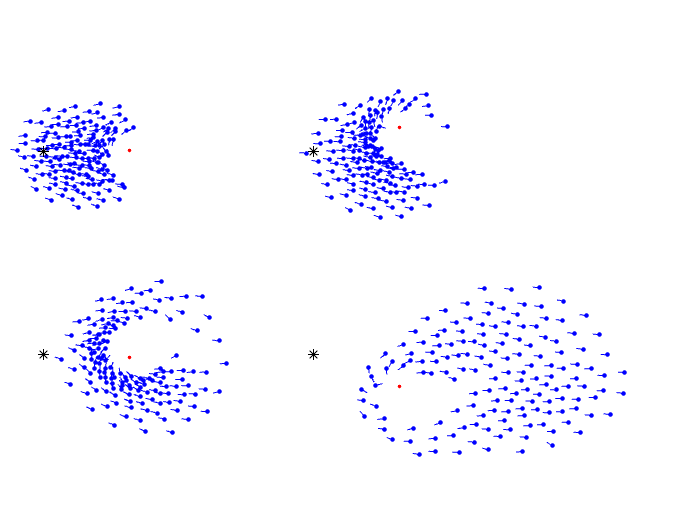

close all;

i=1;
ha = tight_subplot(2,2,[-0.2 -0.2],[.0 .0],[.0 .0]); % Adjusts the gaps
figure;
% plot figure
for t=[16,26,38,71]  
    axes(ha(i));
    % Enable x-ticks and y-ticks
    set(ha(i), 'XTickMode', 'auto', 'XTickLabelMode', 'auto');
    set(ha(i), 'YTickMode', 'auto', 'YTickLabelMode', 'auto');
    hold on;
    % block
    scatter(circle_cent(t,1),circle_cent(t,2),'.','red');
    % nodes
    scatter(x(1,:,t),x(2,:,t),60,'.','b');
    % tail
    plot(Xtail(:,t), Ytail(:,t), '-b');
    % start and end points
    scatter(start_point(1),start_point(2),'*','black')
    fill([wt(1)-0.5,wt(1)+0.5,wt(1)+0.5,wt(1)-0.5], [wt(2)-0.5,wt(2)-0.5,wt(2)+0.5,wt(2)+0.5], 'r', 'EdgeColor', 'none')
    % axis (xy limit)
    axis([-5 42 Ymin Ymax]);

       axis off; 
set(gcf, 'MenuBar', 'none');
set(gcf, 'ToolBar', 'none'); 
set(gcf, 'NumberTitle', 'off'); 

%     axis equal
    if mod(i,2) == 0
    yticks([]);
    end
    if i < 3
        xticks([]);
    end
    xlabel(['i=' num2str(t-1)])
    hold off
    i=i+1;
end  

function h = circle(x,y,r)
th = 0:pi/50:2*pi;
xunit = r * cos(th) + x;
yunit = r * sin(th) + y;
h = plot(xunit, yunit,'MarkerSize',2,'Color',[0.4,0,0.6]);
end